# IK - Pseudoinverse

% Parámetros DH del UR3e

syms theta1 theta2 theta3 theta4 theta5 theta6 real

d = [0.15185, 0.0, 0.0, 0.13105, 0.08535, 0.0921+0.2286];

a = [0.0, -0.24355, -0.2132, 0.0, 0.0, 0.0];

alpha = [pi/2, 0.0, 0.0, pi/2, -pi/2, 0.0];

DH = [theta1,d(1),a(1),alpha(1);theta2,d(2),a(2),alpha(2);theta3,d(3),a(3),alpha(3);theta4,d(4),a(4),alpha(4);theta5,d(5),a(5),alpha(5);theta6,d(6),a(6),alpha(6)];

% Condición inicial, tolerancia del error y número máximo de iteraciones

q0 = deg2rad([35;-95;-60;0.0;40;0.0]) % Se puede cambiar

q0 =     0.6109
   -1.6581
   -1.0472
         0
    0.6981
         0



tol = 1e-3;

maxiter = 1e4;

% Ejemplo --> Conjunto de poses siguiendo un circulo, se puede cambiar por
% una sola pose.

theta = 0:5:360;

% x = 0.6*ones(73);
% y = -0.06 + 0.15*cosd(theta);
% z = 0.44 + 0.15*sind(theta);

x=0.6

x = 0.6000

y=-0.06+0.15

y = 0.0900

z=0.44+0.15

z = 0.5900

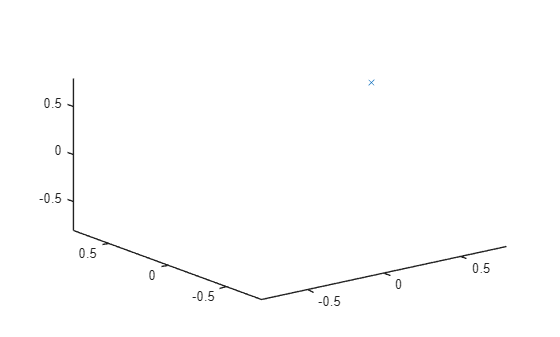


q_s = [];
x_s = [];
y_s = [];
z_s = [];

cont = 0;

for i = 1:1:length(x)

    T = [0,0,1,x(i);-1,0,0,y(i);0,-1,0,z(i);0,0,0,1];

    % Para cada pose deseada, llamamos a la funcuón pseudoinversa

    q_p = pseudo_inversa(T,q0,tol,maxiter,DH);

    % Trayectoria solución (consistente en todas las soluciones -- una por
    % pose). Si en el ejemplo solo hay una pose, q_s solo tiene un
    % elemento, q_p.

    q_s = [q_s;q_p'];

    % Esto solo se hace para garantizar la convergencia cuando hay más de una
    % pose deseada. Usamos la solución como condición inicial del siguiente
    % problema para garantizar una rapida convergencia.

    q0 = q_p;

    % Aplicamos la cinemática directa, para ver la trayectoria en espacio
    % Cartesiano o para comprobar que la solución es la correcta.

    T_s = FK(DH,6);
    T_s = double(subs(T_s,{theta1,theta2,theta3,theta4,theta5,theta6},q_p'));

    x_s = [x_s,T_s(1,4)];
    y_s = [y_s,T_s(2,4)];
    z_s = [z_s,T_s(3,4)];

    cont = cont+1;

end

plot3(x_s,y_s,z_s,'x')
hold on
plot3(x,y,z,'r')
hold off
axis([-0.8 0.8 -0.8 0.8 -0.8 0.8])

% Función que calcula la cinemática inversa con el metodo de la
% pseudoinversa.

function q = pseudo_inversa(pose,q0,tol,maxiter,DH)

    syms theta1 theta2 theta3 theta4 theta5 theta6 real

    % Configuración inicial y posición y orientación predeterminadas (la última expresada como un cuaternión). Es-
    % tas últimas se almacenan por separado para calcular el error correspondiente.

    qi = q0;
    pd = pose(1:3,4);
    Rd = pose(1:3,1:3);
    uqd = quaternion(Rd);

    % Inicialzamos el error en un valor elevado.

    e = 1;

    % Calculo la matriz de la cinemática directa (pose del elemento terminal con respecto a la base) y la matriz Ja-
    % cobiana en simbolico usando los parámetros DH introducidos como input, lo que se basa en funciones dedicadas 
    % que se encuentran al final del script.

    [filas,~] = size(DH);

    % FK

    T = FK(DH,filas);

    p_ee = T(1:3,4);

    % Calculo del Jacobiano

    J = [];

    for i = 0:1:filas-1

        if i == 0

            z_0 = [0,0,1]';
            p_0 = [0,0,0]';

            Ji = [simplify(cross(z_0,p_ee-p_0));z_0];

            J = [J,Ji];

        else

            TI = FK(DH,i);
            zi = TI(1:3,3);
            pii = TI(1:3,4);

            Ji = [simplify(cross(zi,p_ee-pii));zi];

            J = [J,Ji];

        end

    end

    cont = 0;

    while (e >= tol) && (cont <= maxiter)

        % Calculo del error
    
        T_aux = T;
        T_aux = double(subs(T_aux,{theta1,theta2,theta3,theta4,theta5,theta6},qi'));
        pe = T_aux(1:3,4);
        Re = T_aux(1:3,1:3);
        uqe = quaternion(Re);

        J_aux = J;
        J_aux = double(subs(J_aux,{theta1,theta2,theta3,theta4,theta5,theta6},qi'));
    
        % Error de posición y orientación (en cuaterniones porque es más estable) entre la pose actual (asociada con la
        % configuración qi) y la pose deseada.
    
        errorP = pd-pe;
        errorO = uqe(1)*[uqd(2);uqd(3);uqd(4)]-uqd(1)*[uqe(2);uqe(3);uqe(4)] - [0,-uqd(4),uqd(3);uqd(4),0,-uqd(2);-uqd(3),uqd(2),0]*[uqe(2);uqe(3);uqe(4)];
    
        % Para seguir iterando en el bucle while, se calcula la norma del error.
    
        e = 0.5*(norm(errorP)+norm(errorO));
        error = [errorP;errorO];
    
        PJ = pinv(J_aux);
        qi = qi+PJ*error;

        qi = mod(qi + pi, 2*pi) - pi;

        cont = cont+1;

    end

    if cont >= maxiter

        fprintf('ERROR')

    end

    q = qi;

end

function q = tranpose(pose,q0,tol,maxiter,DH)

    syms theta1 theta2 theta3 theta4 theta5 theta6 real

    % Configuración inicial y posición y orientación predeterminadas (la última expresada como un cuaternión). Es-
    % tas últimas se almacenan por separado para calcular el error correspondiente.

    qi = q0;
    pd = pose(1:3,4);
    Rd = pose(1:3,1:3);
    uqd = quaternion(Rd);

    % Inicialzamos el error en un valor elevado.

    e = 1;

    % Calculo la matriz de la cinemática directa (pose del elemento terminal con respecto a la base) y la matriz Ja-
    % cobiana en simbolico usando los parámetros DH introducidos como input, lo que se basa en funciones dedicadas 
    % que se encuentran al final del script.

    [filas,~] = size(DH);

    % FK

    T = FK(DH,filas);

    p_ee = T(1:3,4);

    % Calculo del Jacobiano

    J = [];

    for i = 0:1:filas-1

        if i == 0

            z_0 = [0,0,1]';
            p_0 = [0,0,0]';

            Ji = [simplify(cross(z_0,p_ee-p_0));z_0];

            J = [J,Ji];

        else

            TI = FK(DH,i);
            zi = TI(1:3,3);
            pii = TI(1:3,4);

            Ji = [simplify(cross(zi,p_ee-pii));zi];

            J = [J,Ji];

        end

    end

    cont = 0;

    while (e >= tol) && (cont <= maxiter)

        % Calculo del error
    
        T_aux = T;
        T_aux = double(subs(T_aux,{theta1,theta2,theta3,theta4,theta5,theta6},qi'));
        pe = T_aux(1:3,4);
        Re = T_aux(1:3,1:3);
        uqe = quaternion(Re);

        J_aux = J;
        J_aux = double(subs(J_aux,{theta1,theta2,theta3,theta4,theta5,theta6},qi'));
    
        % Error de posición y orientación (en cuaterniones porque es más estable) entre la pose actual (asociada con la
        % configuración qi) y la pose deseada.
    
        errorP = pd-pe;
        errorO = uqe(1)*[uqd(2);uqd(3);uqd(4)]-uqd(1)*[uqe(2);uqe(3);uqe(4)] - [0,-uqd(4),uqd(3);uqd(4),0,-uqd(2);-uqd(3),uqd(2),0]*[uqe(2);uqe(3);uqe(4)];
    
        % Para seguir iterando en el bucle while, se calcula la norma del error.
    
        e = 0.5*(norm(errorP)+norm(errorO));
        error = [errorP;errorO];
    
        qi = qi+J'*error;

        qi = mod(qi + pi, 2*pi) - pi;

        cont = cont+1;

    end

    if cont >= maxiter

        fprintf('ERROR')

    end

    q = qi;

end

function q = DLS(pose,q0,tol,maxiter,DH)

    syms theta1 theta2 theta3 theta4 theta5 theta6 real

    % Factor de amortiguamiento

    amortiguamiento = 0.1*0.1;

    % Configuración inicial y posición y orientación predeterminadas (la última expresada como un cuaternión). Es-
    % tas últimas se almacenan por separado para calcular el error correspondiente.

    qi = q0;
    pd = pose(1:3,4);
    Rd = pose(1:3,1:3);
    uqd = quaternion(Rd);

    % Inicialzamos el error en un valor elevado.
    e = 1;

    % Calculo la matriz de la cinemática directa (pose del elemento terminal con respecto a la base) y la matriz Ja-
    % cobiana en simbolico usando los parámetros DH introducidos como input. Se puede hacer de otras maneras reusando
    % todas las funciones hechas en las prácticas anteriores.

    [filas,~] = size(DH);

    T = FK(DH,filas);

    p_ee = T(1:3,4);

    J = [];

    for i = 0:1:filas-1

        if i == 0

            z_0 = [0,0,1]';
            p_0 = [0,0,0]';

            Ji = [simplify(cross(z_0,p_ee-p_0));z_0];

            J = [J,Ji];

        else

            TI = FK(DH,i);
            zi = TI(1:3,3);
            pii = TI(1:3,4);

            Ji = [simplify(cross(zi,p_ee-pii));zi];

            J = [J,Ji];

        end

    end
    
    cont = 0;

    while (e >= tol) && (cont <= maxiter)

        T_aux = T;
        T_aux = double(subs(T_aux,{theta1,theta2,theta3,theta4,theta5,theta6},qi'));
        pe = T_aux(1:3,4);
        Re = T_aux(1:3,1:3);
        uqe = quaternion(Re);

        J_aux = J;
        J_aux = double(subs(J_aux,{theta1,theta2,theta3,theta4,theta5,theta6},qi'));
    
        % Error de posición y orientación (en cuaterniones porque es más estable) entre la pose actual (asociada con la
        % configuración qi) y la pose deseada (tal y como viene en la diapositiva).
    
        errorP = pd-pe;
        errorO = uqe(1)*[uqd(2);uqd(3);uqd(4)]-uqd(1)*[uqe(2);uqe(3);uqe(4)] - [0,-uqd(4),uqd(3);uqd(4),0,-uqd(2);-uqd(3),uqd(2),0]*[uqe(2);uqe(3);uqe(4)];
    
        % Para seguir iterando en el bucle while, se calcula la norma del error.
    
        e = 0.5*(norm(errorP)+norm(errorO));
        error = [errorP;errorO];
    
        % Calculo del parámetro alpha

        Jbis = J_aux*J_aux'; 
        Jbisbis = Jbis+amortiguamiento*eye(6);
        L = inv(Jbisbis);
        Jinv = J_aux'*L;
        
        qi = qi+Jinv*error;

        qi = mod(qi + pi, 2*pi) - pi;

        cont = cont+1;

    end

    q = qi;

end

% Cuaternion a matriz de rotación.

function q = quaternion(R)

    q0 = 0.5 * sqrt(1 + R(1,1) + R(2,2) + R(3,3));
    q1 = sign(R(3,2)-R(2,3))*sqrt(1+R(1,1)-R(2,2)-R(3,3));
    q2 = sign(R(1,3)-R(3,1))*sqrt(1+R(2,2)-R(3,3)-R(1,1));
    q3 = sign(R(2,1)-R(1,2))*sqrt(1+R(3,3)-R(1,1)-R(2,2));
    
    q = [q0, q1, q2, q3];

end

% Cinemática directa y cinemática hasta la articulación i.
          
function T = FK(DH_param,art)

    % Matriz de transformación homogénea a actualizar

    T = eye(4);

    for i = 1:art

        % Parámetros DH para la articulación actual

        theta = DH_param(i, 1);
        d = DH_param(i, 2);
        a = DH_param(i, 3);
        alpha = DH_param(i, 4);

        % Calcular la matriz de transformación homogénea para la articulación actual

        A_i = [cos(theta),-sin(theta)*cos(alpha),sin(theta)*sin(alpha), a*cos(theta);
               sin(theta),cos(theta)*cos(alpha),-cos(theta)*sin(alpha), a*sin(theta);
               0,sin(alpha),cos(alpha),d;
               0,0,0,1];

        % Multiplicar de forma consecutiva las matrices A_i obtenidas por cada articulación
        % hasta llegar a la última articulación.

        T = simplify(T*A_i);

    end
end